clc;
clearvars;

Variables:

P3Q2_LPC = 3;
P3Q2_HPC = 5;
y_c = 1.4;
y_t = 1.33;
M = 0.2;
ETHA_Comp = 0.8;
ETHA_Comb = 0.95;
T3 = 1600;
Cp_hot = 1150;
Cp_cold = 1000;
LCV = 43 * 10^6;
ETHA_turb = 0.85;
R = 287.5;
Bleed1 = 0;                             % Bleed air from compressor to outlet     (%)
Bleed2 = 0;                             % Bleed air from compressor to LPT        (%)
Bleed3 = 0;                             % Bleed air from compressor to HPT        (%)
Bleed4 = 0;                             % Bleed air to first LPT nozzle           (%)
Bleed5 = 0;                             % Bleed air to second LPT nozzle          (%)

HMI input:

% set these booleans as following -> hasBleed = inputHMI
hasBleed = true;
isDoubleSpool = false;                  % Checks if the user inputs a single or double spool engine
isPolytropic = true;                    % Checks if the user inputs a polytropic of isentropic efficiency
if hasBleed
    % set these to the input from the HMI like this -> Bleed1 = inputBleed1
    % Bleed1 = 0;                             
    % Bleed2 = 0;                             
    % Bleed3 = 0;                             
    % Bleed4 = 0;                             
    % Bleed5 = 0;                             
end


Height input, temperature and pressure output:

h = [0, 100, 200, 300, 400, 500, 600, 700, 800, 900, 1000, 2000, 3000, 4000, 5000, 6000, 7000, 8000, 9000, 10000, 20000, 30000, 40000];

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));

T0 =(h * Lb) + Tb;

Intake conditions:

W0 = 150;

Station 1: LPC (low pressure compressor) inlet

T1 = T0 * (1 + ((y_c-1)/2) * M^2);
P1 = P0 * (T1/T0)^(y_c/(y_c-1));
W1 = W0;                            % Nothing is added to the flow

Station 1_5: LPC

P1_5 = P1 * P3Q2_LPC;
T1_5 = T1 * (1 + ((P1_5/P1)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
W1_5 = W0;                           % Nothing is added to the flow

Station 2: HPC (high pressure compressor)

P2 = P1_5 * P3Q2_HPC;
T2 = T1_5 * (1 + ((P2/P1_5)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
W2 = W1_5;                           % Nothing is added to the flow

Station 3: Combustor

P3 = P2 * ETHA_Comb;
T3;
Q = W2 * Cp_hot * (T3 - T2);
WF = Q/LCV;
W3 = WF + W2;

Station 3_5: HPT (high pressure turbine)

WHPC = W2 * Cp_cold * (T2 - T1_5);
T3_5 = T3 - (WHPC./(W3.* Cp_hot));
P3_5 = P3.* (1- (1-(T3_5./T3))/ETHA_turb).^(y_t/(y_t- 1));
W3_5 = W3;                           % Nothing is added to the flow

Station 4: LPT (low pressure turbine)

WLPC = W1 * Cp_cold * (T1_5 - T0);
T4 = T3_5 - (WLPC./(W3.* Cp_hot));
P4 = P3_5 * (1 - (1-(T4/T3_5))/ ETHA_turb)^(y_t/(y_t- 1));
W4 = W3_5;                           % Nothing is added to the flow

Station 5: Nozzle 

T5 = T4;
P5 = P4;
W5 = W4;

Calculating static conditions:

Ps = P5/(1 + (y_c - 1)/2)^(y_c/(y_c-1));
Ts = T5/(1 + (y_c - 1)/2);

Calculating Jet Velocity:

Vj = sqrt(y_c * R * Ts);

Calculate static density:

rho = Ps * 1000/(R * Ts);

Calculate nozzle area required:

An = W0./(Vj * rho);

Calculate Thrust: (N)

Fn = (W0 + WF).* Vj + An.* (Ps - P0).* 1000;

Calculate SFC (specific fuel consumption): (g/s kN)

SFC = (WF./Fn).* 1000000;

Calculate ETATH (thermal efficiency):

ETATH = 100.*(3600./(SFC.* LCV/10^5));

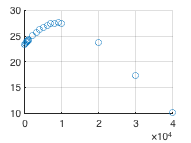

s1 = scatter (h, SFC);
grid on;

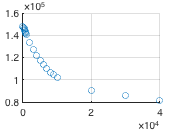


s2 = scatter (h, Fn);
grid on;

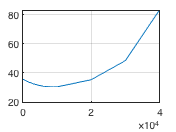


s3 = plot (h, ETATH);
grid on;